## Questions from the paper.

(a). 

(b). 

## KaiC Model

Autophosphorylation model:


$${\frac{dK_p}{dt}} = \left({b \frac{K_P^n}{K_M^n+K_P^n}} + 0.1\right)\left(K_{tot}-K_P\right) - P_P.K_P$$


Dephosphorylation model:


$${\frac{dP_p}{dt}} = k\left({ a\frac{K_P^6}{K_M^6+K_P^6}} - P_P\right)$$


#### Parameters

% For autophosphorylation.
Ktot = 3;                   %Total kinase (phosph. and unphosph.)
K_P = [0:Ktot/100:Ktot];    %Phosphorylated (active) kinase
K_M = 1;                    %K_M for activating of the kinase & phosphatase
b = 0.8;                    %scaling in dK_P/dt
n = 6;                      %cooperativity

% For dephosphorylation.
a = 2;                      %scaling in dP_P/dt

#### Nullclines

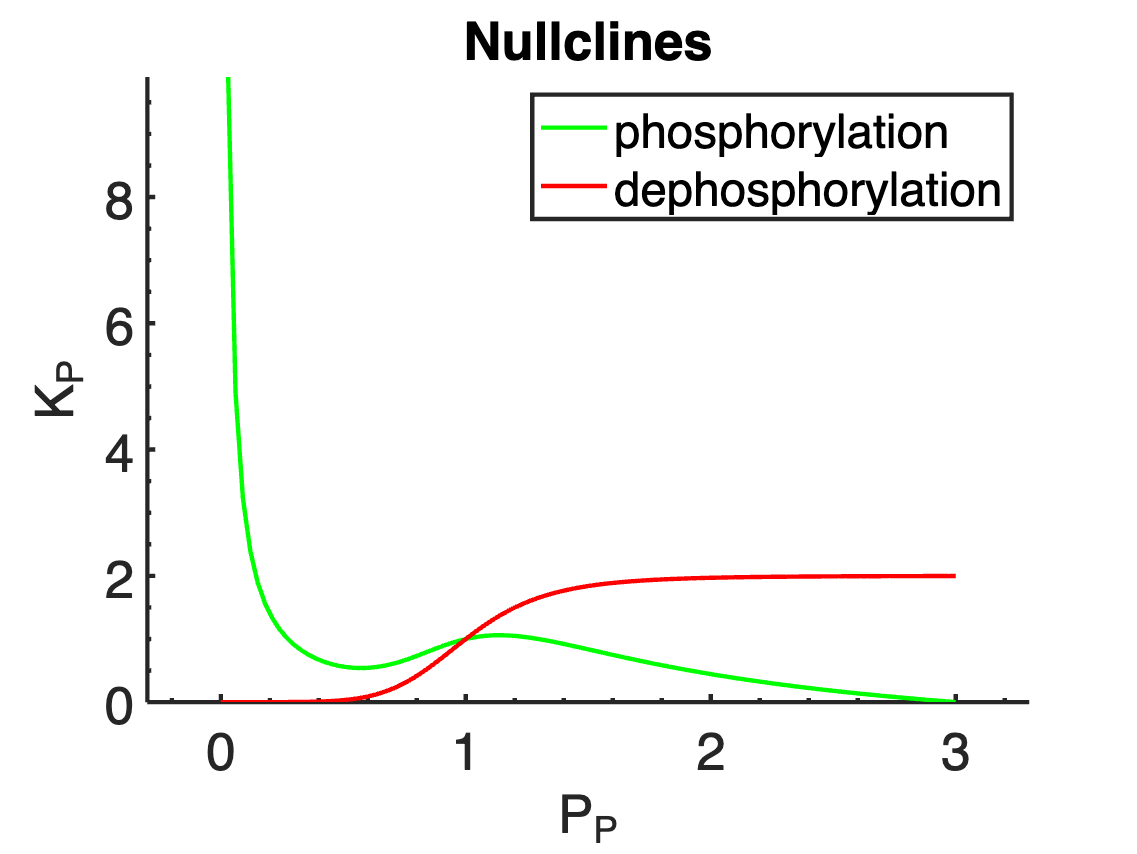

% the dKP nullcline (Psolve):
Psolve_phospho = (b.*K_P.^n./(K_M^n + K_P.^n)+0.1).*(Ktot -K_P)./K_P;

% the dKP nullcline (Psolve):
Psolve_dephospho = a.*K_P.^6./(K_M^6 + K_P.^6);

figure; hold on; zoom on;
% plot nullcline.
plot(K_P, Psolve_phospho, 'g-');
plot(K_P, Psolve_dephospho, 'r-');
% set plot parameters.
title('Nullclines');
xlabel('P_P');
ylabel('K_P');
legend('phosphorylation', 'dephosphorylation');
PrettyFig;